# Determine Camera Pose from World-to-Image Correspondences

Load previously calculated world-to-image correspondences.

load("worldToImageCorrespondences.mat");
cameraParams.ImageSize = [128 128];
intrinsics = cameraParams.Intrinsics;

Estimate the world camera pose.

worldPose = estworldpose(imagePoints,worldPoints,intrinsics);

Plot the world points.

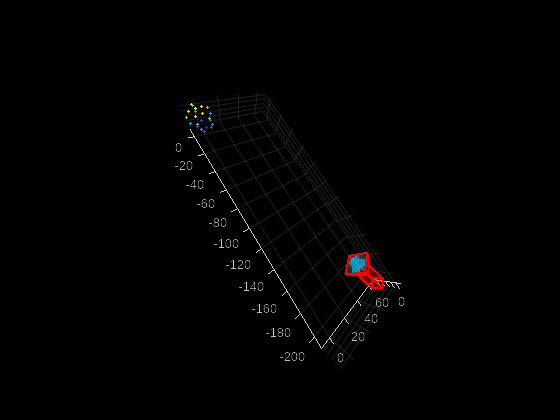

pcshow(worldPoints,VerticalAxis="Y",VerticalAxisDir="down", ...
    MarkerSize=30);
hold on
plotCamera(Size=10,Orientation=worldPose.R', ...
    Location=worldPose.Translation);
hold off

worldPoints = [worldPoints'; ones(1, size(worldPoints, 1))];
projectCameraPoints = [intrinsics.K, [0 0 0]'] * worldPose.invert.A * worldPoints;
projectCameraPoints = projectCameraPoints ./ projectCameraPoints(3, :);
reprojectionError = sum(abs(projectCameraPoints(1:2, :) - imagePoints'), "all");

*Copyright 2022 The MathWorks, Inc.*